# Stima LS di segnali sinusoidali - Soluzione

Sono stati acquisiti, con frequenza di campionamento $f_S = 1 \;\text{kHz}$, $1000$ campioni di un segnale $y(t)$ costituito dalla somma di due segnali sinusoidali 


$$y(t) = \vartheta_1\cdot \sin\left(\bar{\omega}_1\,t+\bar{\delta}_1\right) + \vartheta_2\cdot \cos\left(\bar{\omega}_2\,t+\bar{\delta}_2\right)+\epsilon(t)  \qquad t=k \Delta\,,\quad k=1,\,2,\,\ldots\,N $$


Del segnale sono **noti** i seguenti parametri:

- pulsazione $\bar{\omega}_1$ : $\bar{\omega}_1 = 2\,\pi\cdot 50 \; \text{rad/s}$

- pulsazione $\bar{\omega}_2$ : $\bar{\omega}_2 = 2\,\pi\cdot 150  \; \text{rad/s}$

- sfasamento $\bar{\delta}_1$ : $\bar{\delta}_1 = -\frac{\pi}{9}$

- sfasamento $\bar{\delta}_2$ :  $\bar{\delta}_2 = \frac{2\,\pi}{5}$

mentre sono **incogniti** i valori delle ampiezze $\vartheta_1$ e $\vartheta_2$.

I campioni acquisiti ed i valori dei parametri noti sono a disposizione nel MAT file "StimaLS.MAT"

Determinare i valori dei parametri incogniti $\vartheta_1$ e $\vartheta_2$ utilizzando uno **stimatore ai minimi quadrati.**

**Suggerimento**

L' espressione di $y(t)$ può essere riscritta in questo modo


$$y(t) = \varphi^{\top}(t) \cdot \vartheta + \epsilon(t)$$


dove


$$\varphi(t) = \left[ \begin{array}{c} \varphi_1(t) \\ \varphi_2(t) \end{array} \right] \qquad \vartheta =  \left[ \begin{array}{c} \vartheta_1 \\ \vartheta_1 \end{array} \right]$$


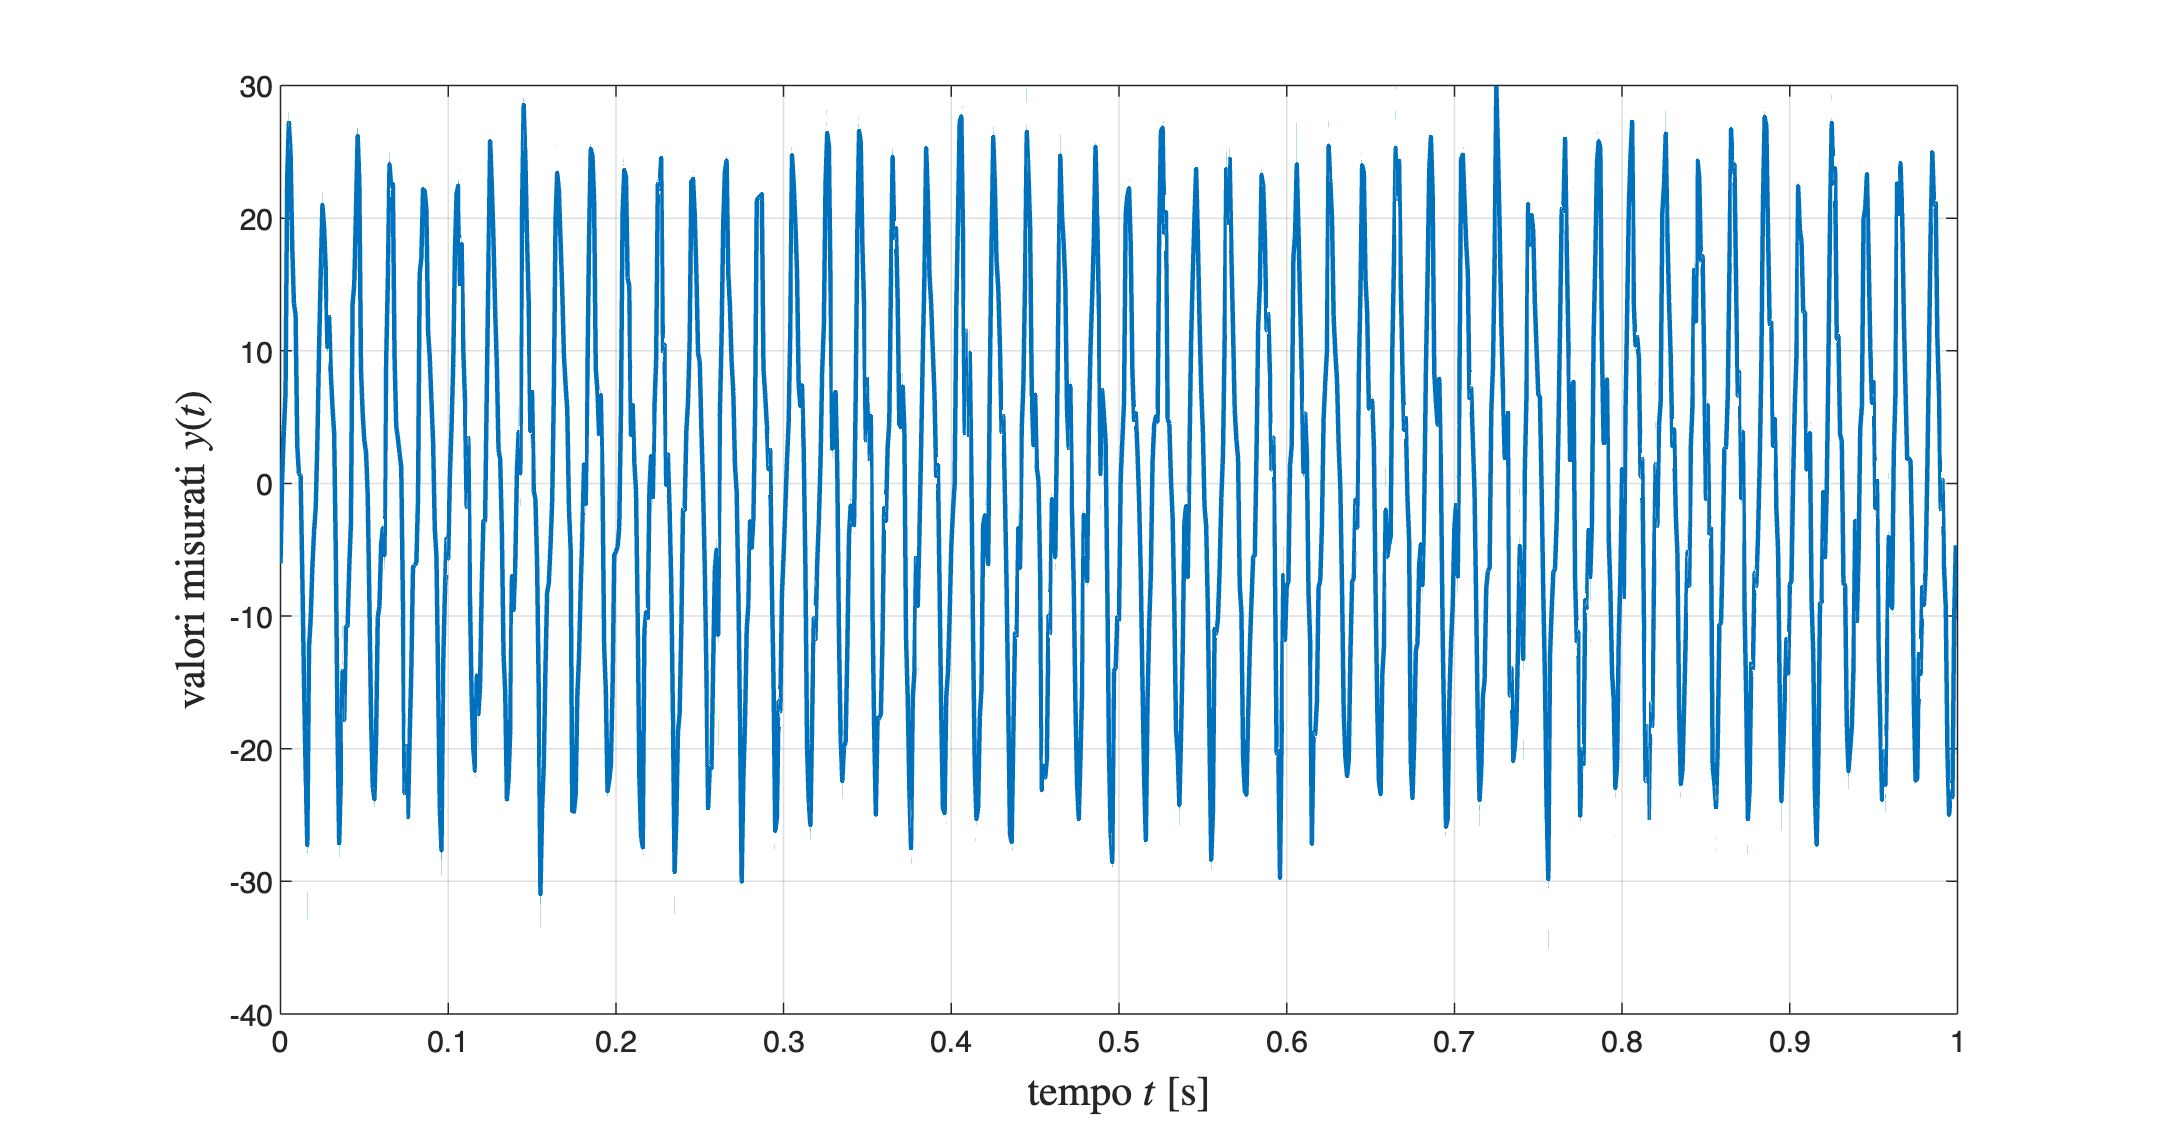

clear
close all
clc

load StimaLS.MAT

Fs = 1e3; % kHz
Ts = 1/Fs;

omega1 = 2*pi*50;
omega2 = 2*pi*150;
delta1 = -pi/9;
delta2 = 2*pi/5;

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
plot(t, y_t, 'LineWidth', 1.5);
grid on;
xlabel('tempo $t$ [s]','Interpreter','latex','FontSize',14);
ylabel('valori misurati $y(t)$','Interpreter','latex','FontSize',14);

## Soluzione

Riscrivo l'espressione di $y(t)$ mettendo in evidenza i parametri incogniti $\vartheta_1$ e $\vartheta_2$ rispetto alle espressioni note (quelli che diventeranno i "regressori")


$$y(t) = \big[ \begin{array}{cc}
\sin\left(\bar{\omega_1}\,t+\bar{\delta_1}\right) & \cos \left( \bar{\omega_2}\,t+\bar{\delta_2}\right) \end{array} \big] \cdot
\left[ \begin{array}{c}
\vartheta_1 \\
\vartheta_2
\end{array} \right] +\epsilon(t)$$


Così è evidente che


$$\varphi(t) = \left[ \begin{array}{c} \varphi_1(t) \\ \varphi_2(t) \end{array} \right] =
\left[ \begin{array}{c}
\sin\left(\bar{\omega_1}\,t+\bar{\delta_1}\right)  \\
\cos \left( \bar{\omega_2}\,t+\bar{\delta_2}\right)
\end{array} \right]$$


e dato che $t=k\,\Delta$ posso scrivere


$$\varphi(k\,\Delta) = \left[ \begin{array}{c} \varphi_1(k\,\Delta) \\ \varphi_2(k\,\Delta) \end{array} \right] =
\left[ \begin{array}{c}
\sin\left(\bar{\omega_1}\,k\,\Delta+\bar{\delta_1}\right)  \\
\cos \left( \bar{\omega_2}\,k\,\Delta+\bar{\delta_2}\right)
\end{array} \right]$$


ed in definitiva, utilizzando tutti i dati acquisiti


$$\Phi \vartheta = Y \; \Longleftrightarrow \; 
\left[ \begin{array}{cc} \sin\left(\bar{\omega_1}\,\Delta+\bar{\delta_1}\right)  & \cos \left( \bar{\omega_2}\,\Delta+\bar{\delta_2}\right) \\
\sin\left(\bar{\omega_1}\cdot2\,\Delta+\bar{\delta_1}\right) & \cos \left( \bar{\omega_2}\cdot2\,\Delta+\bar{\delta_2}\right) \\
\vdots & \vdots \\
\sin\left(\bar{\omega_1}\cdot N\,\Delta+\bar{\delta_1}\right)  & \cos \left( \bar{\omega_2}\cdot N\,\Delta+\bar{\delta_2}\right)
\end{array} \right] \cdot 
\left[ \begin{array}{c}
\vartheta_1\\
\vartheta_2
\end{array} \right] = 
\left[ \begin{array}{c}
y(\Delta) \\
y(2\,\Delta) \\
\vdots \\
y(N\,\Delta)
\end{array} \right]$$


% i dati sono in vettori colonna o riga?
whos

  Name        Size              Bytes  Class     Attributes

  Fs          1x1                   8  double              
  Ts          1x1                   8  double              
  delta1      1x1                   8  double              
  delta2      1x1                   8  double              
  omega1      1x1                   8  double              
  omega2      1x1                   8  double              
  t           1x1000             8000  double              
  y_t         1x1000             8000  double              



% costruisco la matrice dei regressori Phi
matPHI = [sin(omega1*t'+delta1) , cos(omega2*t'+delta2)];

matY = y_t';

% verifico che matPHI si amatrice con N righe e 2 colonne
% mentre matY deve essere un vettore colonna con N campioni
whos matPHI matY

  Name           Size            Bytes  Class     Attributes

  matPHI      1000x2             16000  double              
  matY        1000x1              8000  double              



Ora posso risolvere le equazioni normali ai minimi quadrati sfruttando la notazione compatta di MATLAB

hat_theta = matPHI\ matY

hat_theta =    19.8294
    4.9550


In definitiva i parametri cercati sono

hat_theta1 = hat_theta(1)

hat_theta1 = 19.8294

hat_theta2 = hat_theta(2)

hat_theta2 = 4.9550

Posso valutare la varianza dell'errore $\epsilon$ in questo modo

- utilizzo i parametri appena stimati per valutare (ad ogni istante di tempo $t=k\,\Delta\; ,\;k=1,\,2,\,\ldots N$) 


$$\epsilon(k\,\Delta) = y(k\,\Delta) - 
\big[ \begin{array}{cc}
\sin\left(\bar{\omega_1}\,t+\bar{\delta_1}\right) & \cos \left( \bar{\omega_2}\,t+\bar{\delta_2}\right)
\end{array} \big] \cdot 
\left[\begin{array}{c}
\vartheta_1\\
\vartheta_2
\end{array} \right] \qquad k=1,\,2,\,\ldots N$$


- stimo la varianza deell'errore con la varianza campionaria della sequenza degli $\epsilon(k\,\Delta)$

LSregress_err = y_t' - matPHI*[hat_theta1; hat_theta2];
errVAR = var(LSregress_err)

errVAR = 9.0767

### Nota finale

I valori effettivi dei parametri da stimare valgono


$$\vartheta_1^{o} = 20 \qquad \vartheta_2^{o} = 5$$


emntre la varianza dell'errore di regressione utilizzata per generare i dati vale


$$\text{var}\left[ \epsilon\right] = 10$$
